# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
threshold = 0.6;

## Generate a random physical topology

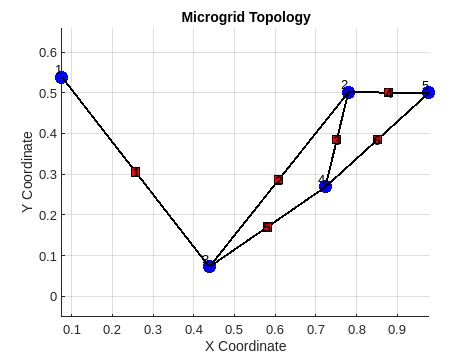

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0

B_il Matrix:
     1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1



coords =     0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999


A_ij =      0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0


B_il =      1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 

## Co-Design Process

parameters

BarGamma = 5000;    % Fixed value for gammaBar
isSoft = 1; % Set to 1 to avoid the hard graph constraint

pScalar = 1/(numOfDGs+numOfLines)

pScalar = 0.0909

piVals = pScalar*ones(1,numOfDGs);
plVals = pScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

MOSEK Version 10.2.1 (Build date: 2024-6-13 06:50:33)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 78              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 163             
  Matrix variables       : 16 (scalarized: 273)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - prima

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1



DG{3}

ans = struct with fields:
              R: 0.0293
              L: 0.0102
              C: 0.0028
              Y: 3.2310
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.4384 0.0721]
             P0: [3×3 double]
             K0: [-8.0690 -0.7265 -12.6342]
             nu: -1.4633e+03
            rho: 108.8591
    gammaTilde0: 133.0245


% Line{5}
% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

## 2. Global Controller Design

[DG,Line,statusGlobalController,gammaTildeVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

MOSEK Version 10.2.1 (Build date: 2024-6-13 06:50:33)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 238             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 238             
  Matrix variables       : 2 (scalarized: 3093)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  :

TVal =     0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000  

TValEigs =    -0.6180
   -0.6180
   -0.6180
   -0.6180
   -0.6180
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


T1Val = 1.0e-20 *

    0.3220         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.3220         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3220         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1322         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1322         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.1322         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.1066     

T1ValEigs = 1.0e-20 *

    0.1066
    0.1066
    0.1066
    0.1297
    0.1297
    0.1297
    0.1322
    0.1322
    0.1322
    0.1646


T2Val = 1.0e-17 *

    0.1250         0         0         0         0         0
         0    0.1091         0         0         0         0
         0         0    0.1137         0         0         0
         0         0         0    0.1176         0         0
         0         0         0         0    0.1090         0
         0         0         0         0         0    0.1184


T2ValEigs = 1.0e-17 *

    0.1090
    0.1091
    0.1137
    0.1176
    0.1184
    0.1250


T3Val = 1.0e-21 *

    0.2093   -0.0000   -0.0000   -0.0004   -0.0000   -0.0000    0.0105   -0.0000    0.0000   -0.0003   -0.0000   -0.0000    0.0001    0.0000    0.0000
   -0.0000    0.2250    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.2251    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004    0.0000    0.0000    0.0793   -0.0000   -0.0000    0.0047   -0.0000   -0.0000    0.0050    0.0000    0.0000    0.0059   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0963   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0963   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0105    0.0000    0.0000    0.0047    0.0000   -0.0000    0.0677   -0

T3ValEigs = 1.0e-21 *

    0.0648
    0.0745
    0.0800
    0.0800
    0.0839
    0.0924
    0.0924
    0.0963
    0.0963
    0.1096


T4Val = 1.0e-21 *

    0.2243         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2243         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2243         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0956         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.0956         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.0956         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0793     

T4ValEigs = 1.0e-21 *

    0.0793
    0.0793
    0.0793
    0.0917
    0.0917
    0.0917
    0.0956
    0.0956
    0.0956
    0.1187


T5Val = 1.0e-22 *

   -0.1505   -0.0000   -0.0000   -0.0037   -0.0000   -0.0000    0.1051   -0.0000    0.0000   -0.0034   -0.0000   -0.0000    0.0015    0.0000    0.0000
   -0.0000    0.0073    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0074    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0037    0.0000    0.0000   -0.1634   -0.0000   -0.0000    0.0469   -0.0000   -0.0000    0.0495    0.0000    0.0000    0.0593   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0065   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0065   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1051    0.0000    0.0000    0.0469    0.0000   -0.0000   -0.1165   -0

T5ValEigs = 1.0e-22 *

   -0.2605
   -0.1988
   -0.1686
   -0.0522
    0.0062
    0.0063
    0.0065
    0.0065
    0.0068
    0.0069


DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusGlobalController = logical
   0


gammaTildeVal = 2.2252e-14


% DG{3}
DG{3}.K

ans = 1×5 cell array
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}


% Line{5}

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

minCost = 100000;

for pScalar = 0.01:0.01:10

    BarGamma = 5;    % Fixed value for gammaBar
    isSoft = 1; % Set to 1 to avoid the hard graph constraint

    piVals = pScalar*ones(1,numOfDGs);
    plVals = pScalar*ones(1,numOfLines);

    [DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 
    [DG,Line,statusGlobalController,gammaTildeVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)
    
    cost = gammaTildeVal;
    % cost = gammaTildeVal + 10000*(1-statusLocalController) + 10000*(1-statusGlobalController) 

    con1 = statusLocalController == 1;
    con2 = statusGlobalController == 1;
    % con3 = norm(DG{1}.K0) < 1000;

    if cost<minCost && con1 && con2
        minCost = cost;
        pStar = pScalar;
    end

end

minCost
pStar

Optimize pVals (Method 2: Use Matlab 'fmincon')

[piVals, plVals] = optimizeCodesignParameters(DG,Line)